## Solve the polarity and force balance equations

The polarity  and force balance equations take the form: 


$$\begin{array}{l}
L_c^{2\;} \nabla^2 \mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)=\mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)\\
\nabla \cdot \sigma =-T_0 \mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right),\;\mathit{\mathbf{r}}\in \Omega 
\end{array}$$


where $\sigma$ is the stress tensor, defined as


$$\sigma =\frac{\eta }{2h}\left(\nabla \mathit{\mathbf{v}}\left(\mathit{\mathbf{r}}\right)+\nabla {\mathit{\mathbf{v}}\left(\mathit{\mathbf{r}}\right)}^T \right)-\frac{\zeta }{h}\mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)\otimes \mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)$$


With boundary conditions:


$$\begin{array}{l}
\mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)\cdot \mathbf{n}=1\\
\sigma \cdot \mathbf{n}\;\;\;\;\;\;=0,\;\;\;\;\;\;\mathit{\mathbf{r}}\in \partial \Omega 
\end{array}$$


Declare the model parameters

%% Model Parameters
global h T0 Lc zeta visc R_crit R h_cell_max cut_angle

h      =  5.0;  % Monolayer height, μm
T0     =  0.5;  % Maximal traction, kPa, 0.2-0.8
Lc     =  25.0; % Nematic lenght, μm
zeta   = -20.0; % zeta = - Contrtactility, kPa, 5-50
visc   =  50e3; % Monolayer viscosity, kPa·s, 3e3-3e4
R_crit = .5*(3*Lc - zeta*h/T0); % Critical radius
R =  200;  % Tissue radius
h_cell_max = 20;
cut_angle = 0;

Create a domain for the cutted circle

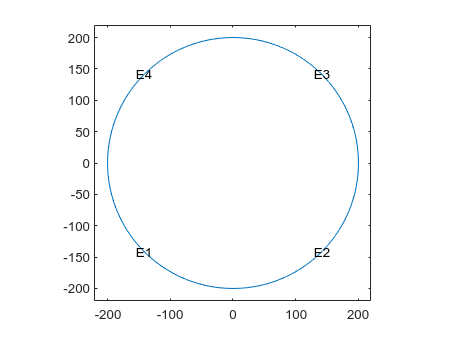

%% Generate the domain
domain = circle_cut(R, cut_angle);

figure; % plot the domain
pdegplot(domain, 'EdgeLabels', 'on')
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

Declare the PDE system derived from the polarity equation as a system symbolic equations. Extract the coefficients of the PDE and return them in symbolic form.

%% Compute coefficients
% Polarity equation
syms p1(x,y) p2(x,y)
pdeeq_p = [...
    laplacian(p1) - p1/Lc^2; ...
    laplacian(p2) - p2/Lc^2; ...
    ];
symCoeffs_p = pdeCoefficients(pdeeq_p,[p1 p2],'Symbolic',true);
%structfun(@disp,symCoeffs_p) % display coefs: m,a, c, f, d
coeffs_p = pdeCoefficientsToDouble(symCoeffs_p);

% Velocity equation
syms v1(x,y) v2(x,y)
pdeeq_v = [...
    (visc*h)*(laplacian(v1,x) + .5*diff(v2,x,y) + .5*laplacian(v1,y)), ...
    (visc*h)*(laplacian(v2,y) + .5*diff(v1,y,x) + .5*laplacian(v2,x)), ...
    ];
symCoeffs_v = pdeCoefficients(pdeeq_v,[v1 v2],'Symbolic',true);
structfun(@disp,symCoeffs_v) % display coefs: m,a, c, f, d

$$0$$

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} -250000 & 0 & 0 & -62500\\ 0 & -125000 & -62500 & 0\\ 0 & -62500 & -125000 & 0\\ -62500 & 0 & 0 & -250000 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$0$$

coeffs_v = pdeCoefficientsToDouble(symCoeffs_v);

Create and solve the polarity model

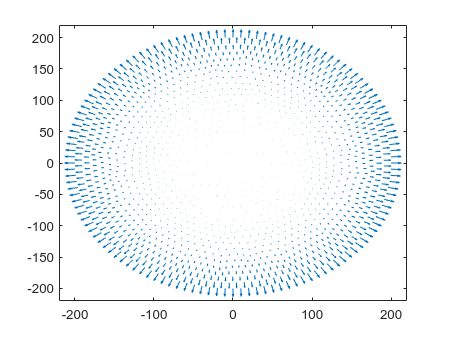

%% Solve polarity
global nodes_p results_p

% Create the model
model = createpde(2);
geometryFromEdges(model,domain);

% Specify coefficients
specifyCoefficients(model,'m',coeffs_p.m,'d',coeffs_p.d, ...
    'c',coeffs_p.c,'a',coeffs_p.a,'f',[0, 0]');

% Apply boundary conditions
applyBoundaryCondition(model,'dirichlet', ...
                             'Edge',1:model.Geometry.NumEdges, ...
                             'r',@normalbc);

% Generate a mesh for the domain
mesh = generateMesh(model,'Hmax',h_cell_max);

% Solve the model to find the polarity
results_p = solvepde(model);
p = results_p.NodalSolution;
nodes_p = mesh.Nodes;

figure;
quiver(nodes_p(1,:)',nodes_p(2,:)',p(:,1),p(:,2))
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

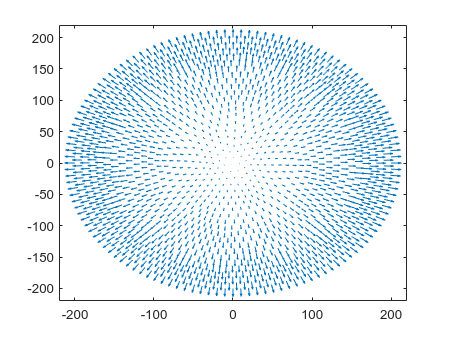

%% Solve velocity
% Create the model
model = createpde(2);
geometryFromEdges(model,domain);

% Specify coefficients
specifyCoefficients(model,'m',coeffs_v.m,'d',coeffs_v.d, ...
    'c',coeffs_v.c,'a',coeffs_v.a,'f',@source);

% Apply boundary conditions
% applyBoundaryCondition(model,'neumann', ...
%                              'Edge',1:model.Geometry.NumEdges, ...
%                              'g',@stressfreebc);
applyBoundaryCondition(model,'dirichlet', ...
                             'Edge',1:model.Geometry.NumEdges, ...
                             'r',@normalbc);


% Generate a mesh for the domain
mesh = generateMesh(model,'Hmax',h_cell_max);

% Solve the model to find the velocity
results_v = solvepde(model);
v = results_v.NodalSolution;
nodes_v = mesh.Nodes;

figure;
quiver(nodes_v(1,:)',nodes_v(2,:)',v(:,1),v(:,2))
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

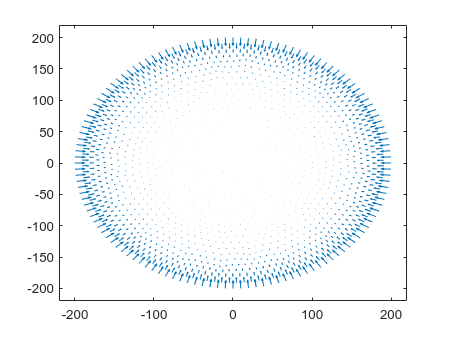


figure;
src = source2plot(nodes_v(1,:),nodes_v(2,:));
quiver(nodes_v(1,:),nodes_v(2,:),src(1,:),src(2,:))
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

%(visc/h)*(laplacian(u3,x) + .5*diff(u4,x,y) + .5*laplacian(u3,y)) + T0*u1 - (zeta/h)*(diff(u1^2,x) + diff(u1*u2,y)); ...
%   (visc/h)*(laplacian(u4,y) + .5*diff(u3,y,x) + .5*laplacian(u4,x)) + T0*u2 - (zeta/h)*(diff(u2^2,y) + diff(u1*u2,x)); ...

Create a function that applies the boundary conditions

function bc = normalbc(location,state)
bc = [location.nx, location.ny];
end

function bc = stressfreebc(location,state)
global zeta
bc = zeta.*[location.nx, location.ny];
end

function domain = circle_cut(R, cut_angle)
x_cut = R*(1-cos(.5*(pi-.5*cut_angle)));

circle = [1 0 0 R]';

rect = [3 4 x_cut R+1 R+1 x_cut -R -R R R]';

circle = [circle;zeros(length(rect) - length(circle),1)]; %append extra zeros
gd = [circle, rect]; % Combine the shapes into one matrix.
ns = char('circle', 'rect')'; % create names for the shapes
sf = 'circle-rect'; % set formula
domain = decsg(gd, 'circle-rect', ns);
end

function src = source(location, state)
global nodes_p results_p T0 zeta h

x = nodes_p(1,:)';
y = nodes_p(2,:)';

px = results_p.NodalSolution(:,1);
py = results_p.NodalSolution(:,2);

[gradx,grady] = evaluateGradient(results_p,x,y,[1,2]);

dxpx = gradx(:,1);
dypx = grady(:,1);
dxpy = gradx(:,2);
dypy = grady(:,2);


src_x = -T0*px + (zeta*h)*(2*px.*dxpx + px.*dypy + dypx.*py);
src_y = -T0*py + (zeta*h)*(2*py.*dypy + px.*dxpy + dxpx.*py);

src = [...
    griddata(x, y, src_x, location.x, location.y, 'cubic')', ...
    griddata(x, y, src_y, location.x, location.y, 'cubic')', ...
    ]';
end

function src = source2plot(xq, yq)
global nodes_p results_p T0 zeta h

x = nodes_p(1,:)';
y = nodes_p(2,:)';

px = results_p.NodalSolution(:,1);
py = results_p.NodalSolution(:,2);

[gradx,grady] = evaluateGradient(results_p,x,y,[1,2]);

dxpx = gradx(:,1);
dypx = grady(:,1);
dxpy = gradx(:,2);
dypy = grady(:,2);


src_x = -T0*px + (zeta/h)*(2*px.*dxpx + px.*dypy + dypx.*py);
src_y = -T0*py + (zeta/h)*(2*py.*dypy + px.*dxpy + dxpx.*py);

src = [...
    griddata(x, y, src_x, xq, yq, 'cubic')', ...
    griddata(x, y, src_y, xq, yq, 'cubic')', ...
    ]';
end
